3.4

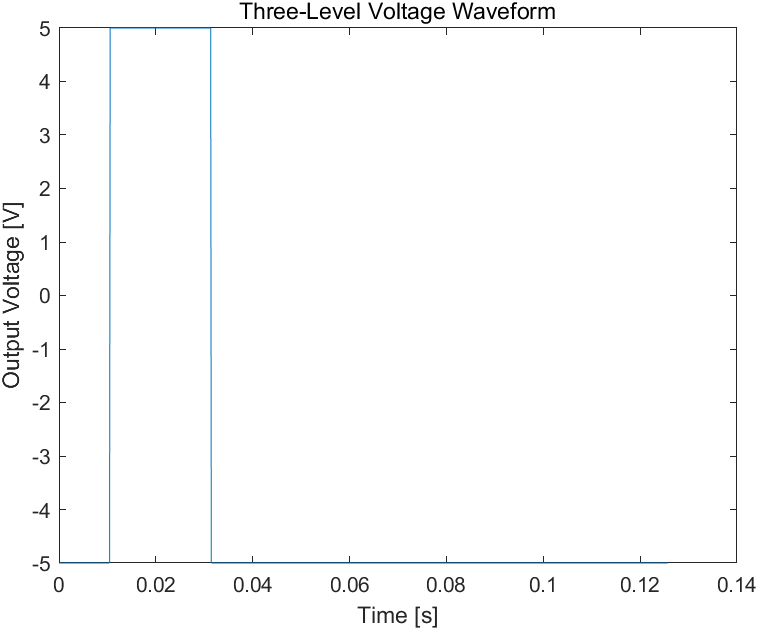

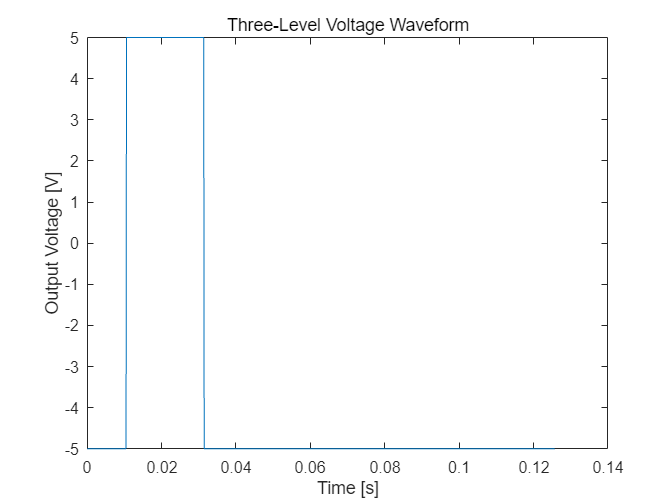

% 변수 설정
w_s = 50; % 각속도 [rad/s]
theta_1 = pi/6; % 각도 [rad]
theta_2 = pi/2; % 각도 [rad]
U_dc = 10; % 직류 전압 [V]

% 시간 범위 설정
t = linspace(0, 2*pi/w_s, 1000);

% 출력 전압 계산
u_a = zeros(size(t)); % 초기화
for i = 1:length(t)
    if w_s*t(i) <= theta_1
        u_a(i) = -U_dc/2;
    elseif w_s*t(i) > theta_1 && w_s*t(i) < theta_2
        u_a(i) = U_dc/2;
    else
        u_a(i) = -U_dc/2;
    end
end

% 그래프 그리기
plot(t, u_a);
xlabel('Time [s]');
ylabel('Output Voltage [V]');
title('Three-Level Voltage Waveform');

3.5

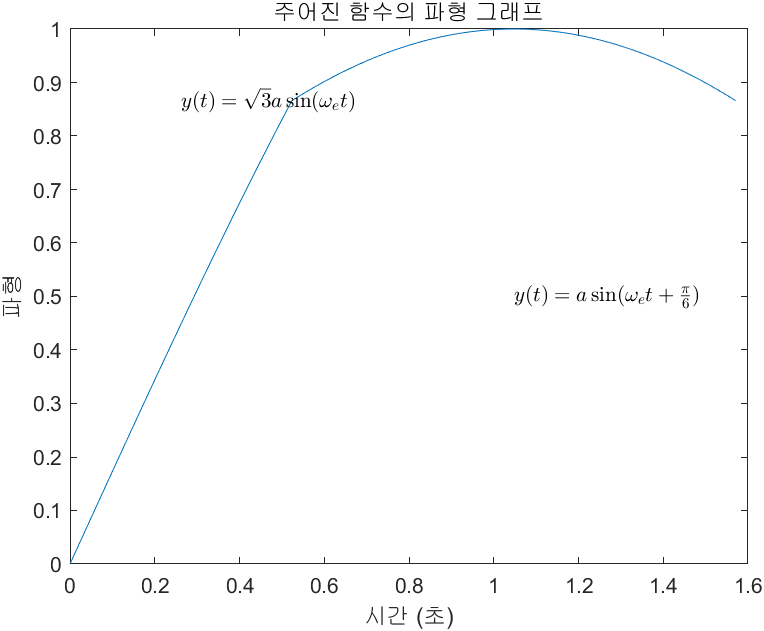

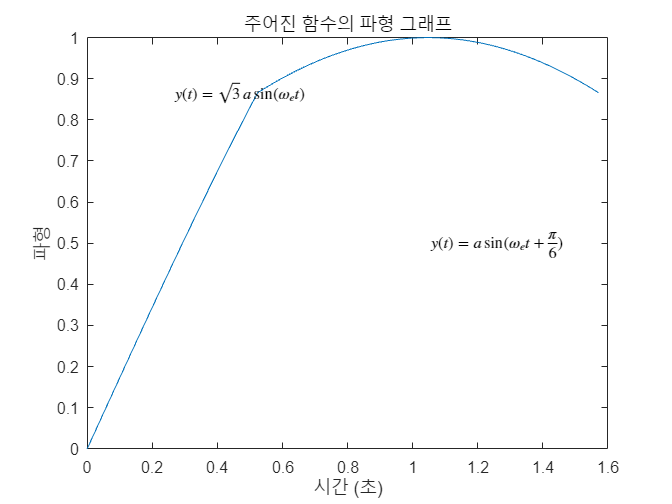

a = 1; % 파형의 진폭
omega_e = 1; % 파형의 각주파수

t = linspace(0, pi/2/omega_e, 1000); % 시간 범위 생성
y = zeros(size(t)); % 출력 벡터 초기화

% 파형 계산
for i = 1:length(t)
    if omega_e*t(i) <= pi/6
        y(i) = sqrt(3)*a*sin(omega_e*t(i));
    else
        y(i) = a*sin(omega_e*t(i)+pi/6);
    end
end

% 시간-파형 그래프 그리기
plot(t, y)
xlabel('시간 (초)')
ylabel('파형')
title('주어진 함수의 파형 그래프')

% 텍스트 표시
text(pi/12/omega_e, sqrt(3)*a/2, '$y(t) = \sqrt{3} a \sin (\omega_e t)$', 'interpreter', 'latex');
text(pi/3/omega_e, a/2, '$y(t) = a \sin (\omega_e t + \frac{\pi}{6})$', 'interpreter', 'latex');
hold on

Harmonic Coefficeint Calculation

3.6


$$$y(t)=a\left(\frac{2}{\sqrt{3}} \sin \left(\omega_e t\right)+\sum_{k=0}^{\infty} \frac{6 \times(-1)^{k+1}}{\pi\left(1-n^2\right)} \sin \left(n \omega_e t\right)\right)$$$


$w_{e}$  는  전기주파수


$$$n=6 k+3, k=0,1,2, \cdots$$$


n=3,9,15

freqE=60;
omegaE=freq2omega(freqE);
n=3*k+3;

'k'은(는) 인식할 수 없는 함수 또는
변수입니다.

endK=100;
k=[1:1:endK]

3.7

y(t)=$$M\left(\sin \left(\omega_e t\right)+\xi \sin \left(3 \omega_e t\right)\right)$$ 


$$$M=\frac{2 a}{\sqrt{3}}, \quad \xi=\frac{3 \sqrt{3}}{8 \pi}$$$


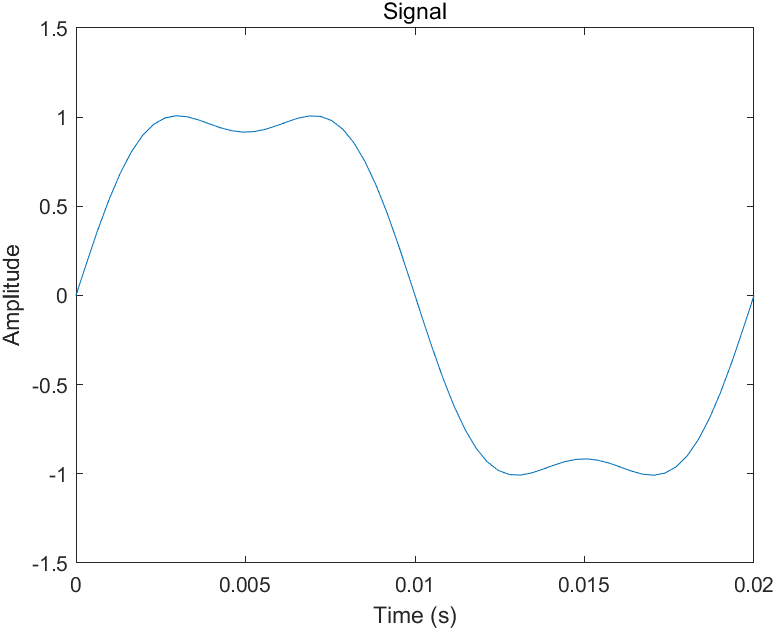

t = linspace(0,0.02,10*2*pi);
w_e = 2*pi*50;
a=1 % 파형의 진폭
M = 2*a/sqrt(3);
xi = 3*sqrt(3)/(8*pi);

y = M*(sin(w_e*t) + xi*sin(3*w_e*t));

plot(t,y)
xlabel('Time (s)')
ylabel('Amplitude')
title('Signal')



3.9 상전압 짝수 함 ( cosin 과 그 테일러급수들은 모두 짝함수)

$$u_a=\frac{U_{d c}}{2}\left(\frac{a_0}{2}+\sum_{n=1}^{\infty} a_n \cos \left(n \omega_s t\right)\right)$$ - 상전압 


$$$\left\{\begin{array}{l}a_0=2 M\left(\sin \left(\omega_e t\right)+\xi \sin \left(3 \omega_e t\right)\right) \\ a_n=\frac{4}{n \pi} \sin \left(\frac{n \pi}{2}+\frac{n M \pi}{2}\left(\sin \left(\omega_e t\right)+\xi \sin \left(3 \omega_e t\right)\right)\right)\end{array}\right.$$$



$$$M=\frac{2 a}{\sqrt{3}}, \quad \xi=\frac{3 \sqrt{3}}{8 \pi}$$$


 높은 차수는 수식으로 작성하지않지만 코드로 구현,

 n=1 ,  n=2 만 수식으로 구해보면 by B.1.2  Harmonic Coefficient Calculation

3.11


$$$a_1 \approx C_{10}+2 C_{12} \cos \left(2 \omega_e t\right)+2 C_{14} \cos \left(4 \omega_e t\right)$$$


3.12


$$$\left\{\begin{array}{l}C_{10}=\frac{4}{\pi} J_0\left(\frac{M \pi}{2}\right) J_0\left(\frac{M \pi \xi}{2}\right) \\ C_{12}=\frac{4}{\pi}\left(J_2\left(\frac{M \pi}{2}\right) J_0\left(\frac{M \pi \xi}{2}\right)-J_1\left(\frac{M \pi}{2}\right) J_1\left(\frac{M \pi \xi}{2}\right)\right) \\ C_{14}=\frac{4}{\pi} J_1\left(\frac{M \pi}{2}\right) J_1\left(\frac{M \pi \xi}{2}\right)\end{array}\right.$$$


Appendix B.1 

$$J_k(x)=\sum_{n=0}^{\infty} \frac{(-1)^n}{n !} \frac{1}{\Gamma(k+n+1)}\left(\frac{x}{2}\right)^{2 n+k}$$  (B.2)

where $$\Gamma(k+n+1)=(k+n) !$$ (B.2)

$$e^{j z \sin \theta}=\sum_{k=-\infty}^{+\infty} J_k(z) e^{j k \theta},|z|<\infty$$ (B.3)

$$\left\{\begin{array}{l}\cos (z \sin \theta)=J_0(z)+2 \sum_{k=1}^{\infty} J_{2 k}(z) \cos (2 k \theta) \\ \sin (z \sin \theta)=2 \sum_{k=0}^{\infty} J_{2 k+1}(z) \sin ((2 k+1) \theta)\end{array}\right.$$ (B.4)


$$$e^{j \theta}=\cos \theta+j \sin \theta$$$



$$$\sin \theta=\frac{e^{j \theta}-e^{-j \theta}}{2 j}$$$



$$\cos(\theta) = \frac{e^{j\theta}+e^{-j\theta}}{2}$$


B.1.2  Harmonic Coefficient Calculation

3.11 rewrite


$$$a_n=\frac{4}{n \pi} \sin \left(\frac{n \pi}{2}+\frac{n M \pi}{2}\left(\sin \left(\omega_e t\right)+\xi \sin \left(3 \omega_e t\right)\right)\right)$$$


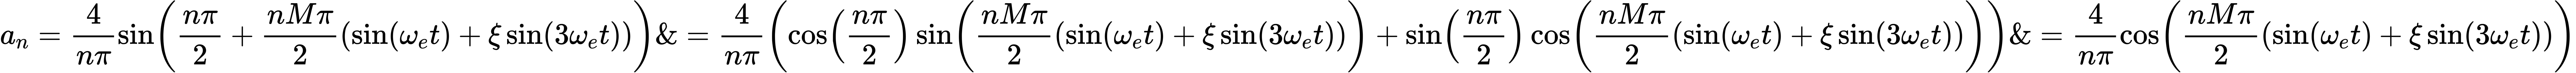

$$a_1=\frac{4}{\pi} \cos \left(\frac{M \pi}{2}\left(\sin \left(\omega_e t\right)+\xi \sin \left(3 \omega_e t\right)\right)\right)$$  (B.5)


$$$=\frac{4}{\pi} \Re\left\{e^{j \frac{M \pi}{2}\left(\sin \left(\omega_c t\right)+\xi \sin \left(3 \omega_c t\right)\right)}\right\}$$$



$$$=\frac{4}{\pi} \Re\left\{e^{j \frac{M \pi}{2} \sin \left(\omega_e t\right)} e^{j \frac{M \pi}{2} \xi \sin \left(3 \omega_e t\right)}\right\}$$$


$$e^{j \frac{M \pi}{2} \sin \left(\omega_e t\right)}=J_0\left(\frac{M \pi}{2}\right)+2 \sum_{k=1}^{\infty} J_{2 k}\left(\frac{M \pi}{2}\right) \cos (2 k \omega_e t)+j 2 \sum_{k=0}^{\infty} J_{2 k+1}\left(\frac{M \pi}{2}\right) \sin \left((2 k+1) \omega_e t\right))$$  (B.6)


$$$e^{j \frac{M \pi \xi}{2} \sin  (3 \omega_e t  )}=J_0 (\frac{M \pi \xi}{2}  )+2 \sum_{k=1}^{\infty} J_{2 k}(\frac{M \pi \xi}{2}  ) \cos (6 k \omega_e t)+j 2 \sum_{k=0}^{\infty} J_{2 k+1}   (\frac{M \pi \xi}{2} ) \sin    ((6 k+3) \omega_e t )$
$$


 고차 성분을 무시하면

$$\left\{\begin{array}{l}e^{j \frac{M \pi}{2} \sin \left(\omega_e t\right)} \approx J_0\left(\frac{M \pi}{2}\right)+2 J_2\left(\frac{M \pi}{2}\right) \cos \left(2 \omega_e t\right)+j 2 J_1\left(\frac{M \pi}{2}\right) \sin \left(\omega_e t\right) \\ e^{j \frac{M \pi \xi}{2} \sin \left(3 \omega_e t\right)} \approx J_0\left(\frac{M \pi \xi}{2}\right)+j 2 J_1\left(\frac{M \pi \xi}{2}\right) \sin \left(3 \omega_e t\right)\end{array}\right.$$  (B.7)

 최종적으로